**PCS 130 Lab 1 - Electric Potential**

Throughout this lab we will utilize matlab (live scripts) to aid in the procedure and analysis on the experiment performed. Live scripts allow us to execute code in line and organize the code and outputs in a notebook like fashion. For more detailed instructions on utilizing matlab live scripts see this link here: [https://www.mathworks.com/help/matlab/live-scripts-and-functions.html](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html)

For this experiment you will get examples on how to do various tasks in matlab such as:

- Creating and indexing variables

- Use data in calculations

- Visualize the data to represent a physical system

**Procedure: Part 1 - "Point-like Electrodes"**

The first part of this lab is to probe points on the conductive paper to visualize the equipotential lines generated for various voltages across a conductive surface. In the code skeleton below is an 'axis' that creates the skeleton for you to visualize the equipotential lines on a plot. For this section, we will use basic variables and data structures in matlab as well as functions to help create this visualization.

Using the code block below, create variables to represent the x,y coordinates of your initial point charges. To create a variable, enter the name you would like to give it followed by the equal sign and a value to assign. Once you have assigned a value, click run section in the task bar of matlab or cmd+enter to run the code.

%Comments can be made in code by adding a '%' sign at the front of your
%text. Comments are notes that appear green in the code that are not executed by the compiler
%and allow you to leave notes.
%Assign a value to x_charge_pos and y_charge_pos by putting a number next
%to the equal sign

x_charge_pos = [0 1 2 2 0; 0 1 2 3 3; 0 1 2 3 0; 27 25 27 27 26]'

x_charge_pos =     4.0000   14.0000   19.0000   10.2000
    5.3000   14.0000   18.8000   10.5000
    5.9000   14.0000   18.0000   10.0000
    6.0000   14.0000   18.0000    9.0000
    5.0000   14.0000   19.8000    8.2000
    5.2000   14.6000   21.2000    7.5000


y_charge_pos = [5 6 7 10 14; 2 3 4 6 10; 0 2 3 4 16; 3 16 11 8 6]'

y_charge_pos =     4.0000    3.0000    3.0000    3.8000
    6.2000    5.0000    4.2000    5.5000
    7.1000    8.2000    7.0000    8.0000
   10.3000   10.2000    9.0000   10.0000
   12.5000   13.8000   13.0000   13.2000
   14.8000   15.8000   16.0000   17.0000


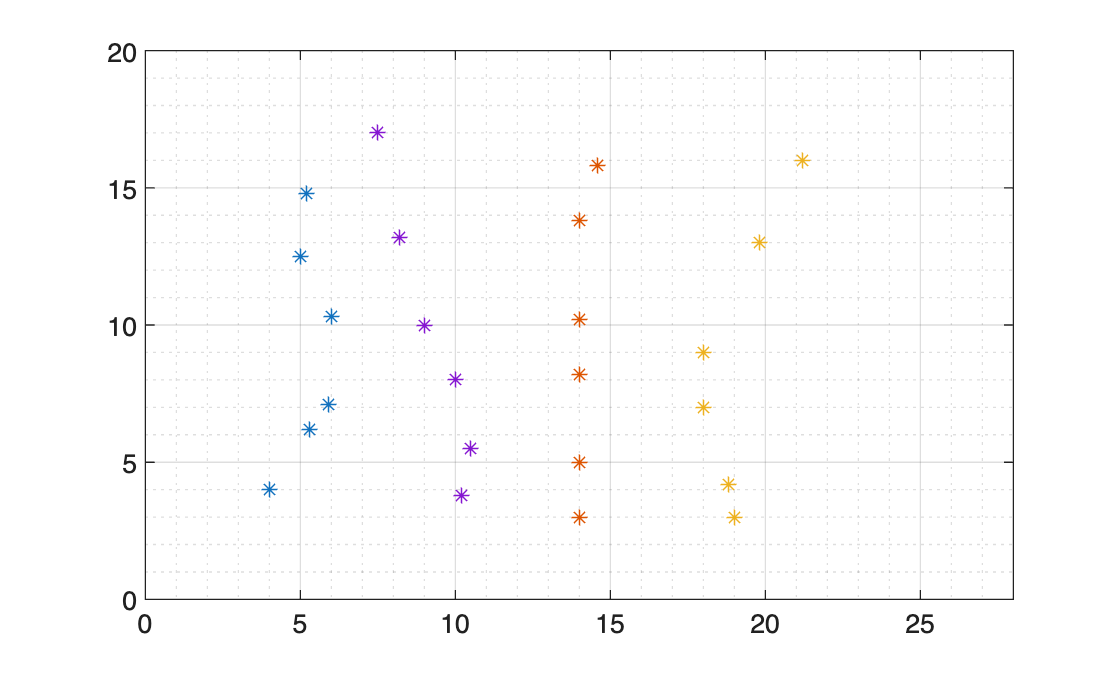

plot(x_charge_pos,y_charge_pos,'*')
xlim([0 28])
ylim([0 20])
grid on
grid minor

Matlab's notebook functionality (.mlx) files allows you to see the inline result of the code you ran. In the generated plot you should see a blue asterisk representing where your point charge is. Notice that we manually set the axes limits using xlim and ylim to represent the axes of the conductive paper. The generated plot will serve as the base axes for which you will plot the rest of the equipotential lines and electrodes.

**Creating a matrix of coordinates**

In the cell below, is an example of another type of data structure called a matrix . A matrix is a data structure that can be used to hold multiple numeric values and has dimensions N x M (where N is the rows and M is the columns). Running the code block below creates a 1 by 5 element matrix. You can see the details of the data structure in the Workspace of matlab (normally on the right hand side of the window). For this lab you will use matrices in order to store the x,y coordinates of equipotential lines into a table.

matrix_example = [ 1 2 3 4 5 ]

matrix_example =      1     2     3     4     5


If you measure a voltage of 2V at the following coordinates: (1,1), (1,2), (1,3) then your code below would look something like this:

For matrices, spaces or commas can be used to add values to a row, while semicolons will create a new row in the matrix. In the example above, the dimensions of the above matrices would be 3x1 (row x column). If you add in an apostrophe symbol (') at the end of a matrix it will invert the columns and rows. To make things easier for plotting, try to structure your matrix of coordinates so that each column of the x_coordinates represents the x coordinates for a given voltage. As an example, see the code below:

This will result in a (2x5) matrix for the x_coordinates and y_coordinates variables.

In the code block below, use the elecrode_x and electrode_x2 variable to represent the x coordinate of your two point charges. Electrode_y will be used to represent the y coordinate. Note that we only need one y coordinate in this case as both point charges should lie on the same height on the paper and so we can re-use the same variable for the future.

%add your x coordinates to the x_coordinates variable and y coordinates to
%the y_coordinates variable.
electrode_x = 1

electrode_x = 1

electrode_x2 = 25

electrode_x2 = 25

electrode_y = 10

electrode_y = 10


%Note that the matrix already has an apostrophe after the square brackets and so
%the output will be flipped. This is so you don't need to add semicolons
%after each element to add elements to your rows.
x_coordinates = [20 22 22 24 20; 13 15 14 16 17; 2 3 6 7 9]'

x_coordinates =     20    13     2
    22    15     3
    22    14     6
    24    16     7
    20    17     9



y_coordinates = [5 4 10 6 7; 5 7 10 10 10; 2 7 8 9 9]'

y_coordinates =      5     5     2
     4     7     7
    10    10     8
     6    10     9
     7    10     9



% The line below organizes your matrices into a table data
% structure for more inituitive use. 
coordinate_table_point = table(x_coordinates,y_coordinates)

coordinate_table_point = 5×2 table
    x_coordinates     y_coordinates 
    ______________    ______________

    20    13     2     5     5     2
    22    15     3     4     7     7
    22    14     6    10    10     8
    24    16     7     6    10     9
    20    17     9     7    10     9


Now that you have your basic table of data set-up, you can go about plotting the visualization of the equipotential lines. To do this the plot() function is used. The plot function takes the x and y values as the first two arguments, with a third argument ('--') to specify the line style. For more information on the plot() function see the documentation [here](https://www.mathworks.com/help/matlab/ref/plot.html) or type 'help plot' in the command window.

In the code block below, pay special attention as to how the table is indexed in order to access the coordinates for your x and y values. For example, the first argument in the plot function takes the name of the variable, 'coordinate_table_point' and it's column 'x_coordinates' by indexing it using dot notation. Note that this is just *one* way of access the data in the table. 

In the last line of code, edit the legend so that it accurately shows what voltage you recorded that line at.

Run the code the visualize your equipotential line.

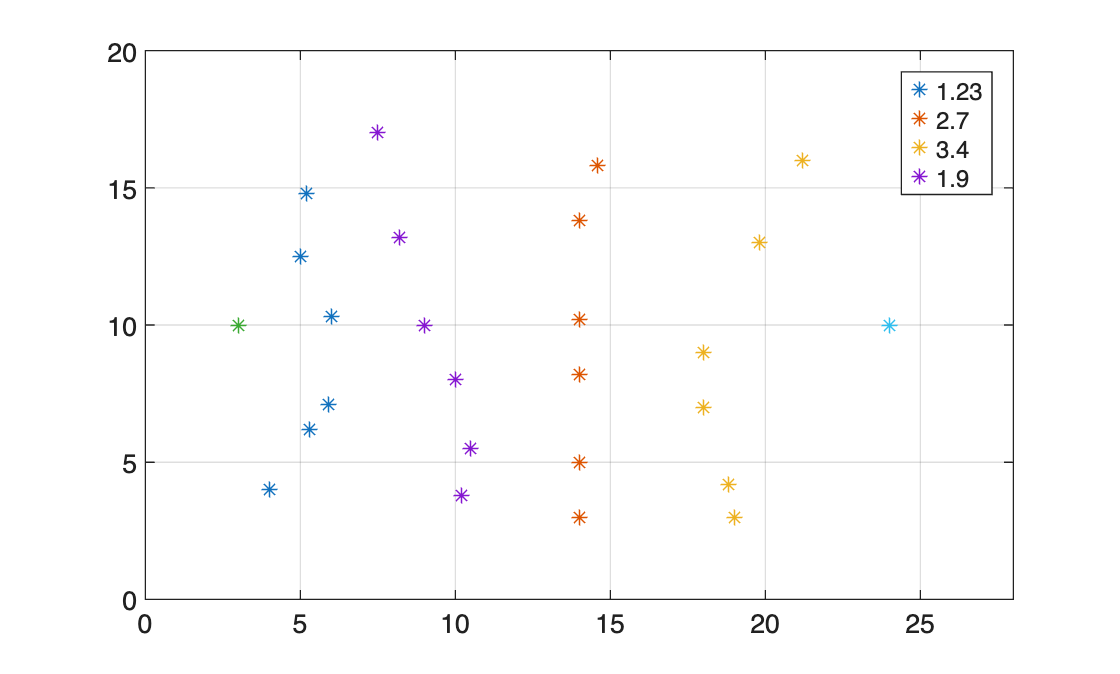

plot(coordinate_table_point.x_coordinates,coordinate_table_point.y_coordinates,'--')
hold on 
plot(electrode_x,electrode_y,'*')
plot(electrode_x2,electrode_y,'*')
hold off
xlim([0,28])
ylim([0,20])
grid on
grid minor
%Change the legend here to make your lines correspond to the actual Voltage
%measured. The legend takes strings as arguments, which is text enclosed in
%brackets such as 'text' Arguments into a function need to be separated by
%commas.
legend('4.10', '3.66','3.01') 

**Part 2:** **Bar Electrodes**

Similar to what was done in part 1, you will collect data on the equipotential line pattern, but this time using bar electrodes. In order to first set-up the visualization, the barlike electrodes will be printed as a line of stars. In the code block below, the linspace (linear space) function is used to create a matrix of 1xN (where N is the length of the matrix), equally spaced numbers from a start number to an end number. Repeat the steps from Part 1, to plot the (x,y) coordinates but instead with the updated visualization of the bar electrodes.

%Note that the bar locations are preset to be at x = 4 and 20cm away. If
%your set-up has a different starting location for the bars then change the
%4 under bar_location_x to the appropriate value in your set-up.

bar_location_y = linspace(5,15,10); 
bar_location_x = ones(1,10)*4; 
bar_location_x2 = bar_location_x + 20; 

x_coordinates_bar = [5 6 7 8; 14 14 14 15; 17 18 19 19]';
y_coordinates_bar = [5 6 7 11; 4 7 10 10; 2 3 4 10]';

bar_table = table(x_coordinates_bar,y_coordinates_bar)

bar_table = 5×2 table
         x_coordinates_bar              y_coordinates_bar      
    ___________________________    ____________________________

    5.5       8      21      14     2.5     1.6       2       1
    6.2     9.2    19.8      14       6     3.4     5.4     3.4
    5.8     8.5      20      14    11.6     6.2    10.8     6.8
    4.8     7.8    20.2     7.8      16    10.6    16.2    10.2
      4     7.2      21    11.8    18.5      14    17.6      16


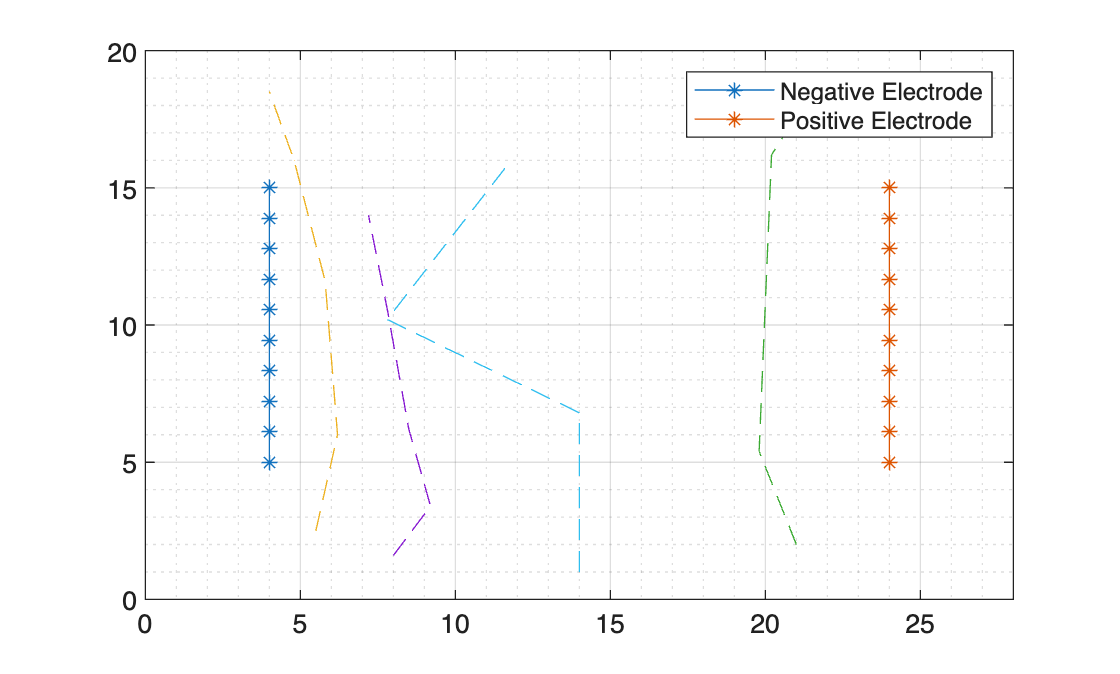

plot(bar_location_x,bar_location_y,'*-')
hold on 
plot(bar_location_x2,bar_location_y,'*-')
plot(bar_table.x_coordinates_bar, bar_table.y_coordinates_bar,'--')
hold off
xlim([0 28])
ylim([0 20])
grid on
grid minor

%Here the negative and positive electrode are already labelled. Add in more
%arguments corresponding to your lines, similar to what you did for the
%point electrodes.
legend('Negative Electrode','Positive Electrode')

**Analyzing V as a function of distance along the centreline.**

For this part of the experiment you are to examine how the voltage changes as you move closer to the other terminal of the electrode. Collect data measuring the voltage along the center line of the as a function of r (distance). Using the code block below, you will create a plot in order to examine how the voltage changes for both the point and bar scenarios. Using the hold on and hold off functions plot both on the same graph.

%In the variable below, create a matrix or data structures the voltages you
%record at a given distance (r) away from the initial electrode.
vx_point = [0.97 0.60 1.49 2.44]


vx_point =

     []



vx_bar = [0.30 0.70 1.48 2.5]


vx_bar =

     []




%In the variable below, record your distance measurements using the
%variable linspace. Linspace (Linear Space) creates equally spaced numbers
%from a start value to end value. What values would you use based on your
%experimental set-up? Hint: Think about the distance between the electrodes
%and how many points your want to take.

r = linspace(5)

Not enough input arguments.

Error in linspace (line 19)
    n = floor(double(n));
    ^^^^^^^^^^^^^^^^^^^^^


%Plot r versus vx below for both point and bar scenarios.
%Use the hold on and hold off functions to preserve the axis so both are on
%one graph.
%For an example on useage oh plot() see the previous sections where you visualized
%the data.
%
%plot()
%hold on
%plot()
%hold off
%Add in chart elements below such as the title, and label axes using the
%functions below
%title()
%ylabel()
%xlabel()


Notice in the initial plot above, that the data does not actually look very linear for the point charge scenario. From your prelab you should have derived an equation that related the magnitude of the electric potential in terms of the natural logarithim of r as shown below:

    
$$V_{\textrm{tot}} =2\textrm{KQln}\left\lbrack \frac{r}{d-r}\right\rbrack$$


Where K is a constant, Q is the charge, d is the distance between the electrodes and r is a point that is some distance away from the negative charge.

In order to correctly plot the Voltage in terms of r, we need to appropriately translate the data acquired by performing a calculation in matlab. Basic operations in matlab include addition (+), subtraction (-), division (/) and multiplication (*). A special notation that is relevant for matlab is the dot '.' notation in front of operators. Recall that the matrix you created for r is some 1xN matrix where N is the number of distance points you measured. In order to tell matlab you want to perform a calculation to each entry (element) in the matrix instead of as a matrix multiplication you need to put a '.' infront of the operator. An example is shown below.

%Below is just normal scalar multiplication
mult_example = 10*10
%Below is Matrix Multiplication (no . in front of multiplication symbol)
mat1 =  [10 10; 10 10]
mat2 =  [1 2; 1 2]'
mat_example = mat1*mat2
%Element by element multiplication 
e_by_e = mat1.*mat2

Matlab operators can be further summarized using the documentation found [here](https://www.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html). 

Apply a transformation of your distance data to instead better represent the equation for the point charge scenario. Replot this plot in terms of the transformed distance measurements and the original V data for the point charges along the centre line.

%Transformation of r data

%log_r = 

%plot(log_r,vx_point)
%Add in chart elements below such as the title, and label axes using the
%functions below. 
%title()
%ylabel()
%xlabel()

**Wrapping Up**

To ensure you have all the data you need for your report, make sure to save your code and submit it to D2L. For your report, you will need to include figures of the generated plots and a table of your data. Plots, figures and tables can be exported out of matlab.